%Script calculates and plots the magnetic field strength vectors
%surrounding a disk cross section with a given radius a and applied current
%I. 


**Properties of circular disk:**

%radius of disk cross section in nanometers
a = 33;

%current through disk cross section in A
I=8.3;
I_in = I/1000;

**Position of desired field measurement:**

xstr = "100";
ystr = "50";

xpos2 = str2double(xstr);
ypos2 = str2double(ystr);

hxpos2 = circxfield(a,xpos2,ypos2,I_in) * 10^9;
hypos2 = circyfield(a,xpos2,ypos2,I_in) * 10^9;




**Magnetic field strength at (X,Y):**

magnitude2 = sqrt((hypos2)^2 + hxpos2^2);

fprintf("The X field component at \n (%.2f,%.2f) is: %.4f A/m", xpos2,ypos2,hxpos2)

The X field component at 
 (100.00,50.00) is: 5283.9441 A/m


fprintf("The Y field component at \n (%.2f,%.2f) is: %.4f A/m", xpos2,ypos2,hypos2)

The Y field component at 
 (100.00,50.00) is: -10567.8882 A/m

fprintf("The magnitude of the field strength a \n (%.2f,%.2f) is: %.4f A/m", xpos2, ypos2, magnitude2)

The magnitude of the field strength a 
 (100.00,50.00) is: 11815.2582 A/m

**Display Parameters:**

arrows = 19;
markersize = 0.95;
a3 = 3*a;
plotrange = 243;


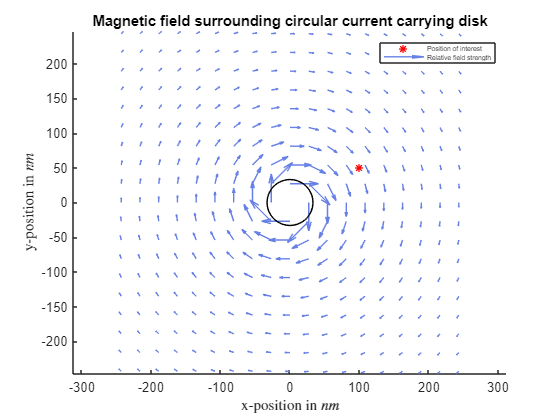

%Plotting range and number of arrows, and matrix representation of (x,y)
%ranges:
ticks = linspace(-plotrange,plotrange,arrows);
[XX,YY] = meshgrid(ticks,ticks);


%magnetic field components produced by disk:

%loops through grid of (x,y) values and creates a matrix of both x and y
%magnetic field components:

n = numel(ticks);
hxmatrix = zeros(n);
for i=1:n
for j=1:n
    hxci = circxfield(a,ticks(j),ticks(i),I);
    hxmatrix(i,j)=hxci;

end
end

hymatrix = zeros(n);
for i=1:n
for j=1:n
    hyci = circyfield(a,ticks(j),ticks(i),I);
    hymatrix(i,j)=hyci;

end
end




%plots  quiver plot of field strength vectors centred at (0,0) with a disk
%superimposed to show the position and relative size of the disk

scatter(xpos2,ypos2,'r', "*", "LineWidth", markersize)
hold on
quiver(ticks,ticks,hxmatrix,hymatrix, 1.2,"color",[0.4,0.5,0.9])
hold off
pos = [-a -a 2*a 2*a];
rectangle('Position',pos,'Curvature',[1 1])
xlabel("x-position in $nm$", "Interpreter","latex")
ylabel("y-position in $nm$", "Interpreter","latex")
title("Magnetic field surrounding circular current carrying disk")
leg2 = legend("Position of interest","Relative field strength");
set(leg2, "fontsize", 5)
axis equal



%Calculates the y Vector component of magnetic field surrounding a circular
%disk of radius a:


function [Hy] = circyfield(a,X,Y,I)
    %a is the radius of the disk
    %X is x position
    %Y is y position
    %I is the value of current through the surface 
    %Returns x component of magnetic field
    p=pi;

    if (X^2+Y^2) >= a^2
        Hy = (I/(2*p))*(1/((X^2+Y^2))) *(-X);

    else 
        Hy = (I/(2*p*(a^2)))*(-X);

    end
end


%Calculates the x Vector component of magnetic field surrounding a circular
%disk of radius a:

function [Hx] = circxfield(a,X,Y,I)
    %a is the radius of the disk
    %X is x position
    %Y is y position
    %I is the value of current through the surface 
    %Returns x component of magnetic field
    p=pi;

    if (X^2+Y^2) >= a^2
        Hx = (I/(2*p))*(1/((X^2+Y^2))) *(Y);

    else 
        Hx = (I/(2*p*(a^2)))*(Y);

    end
        
end